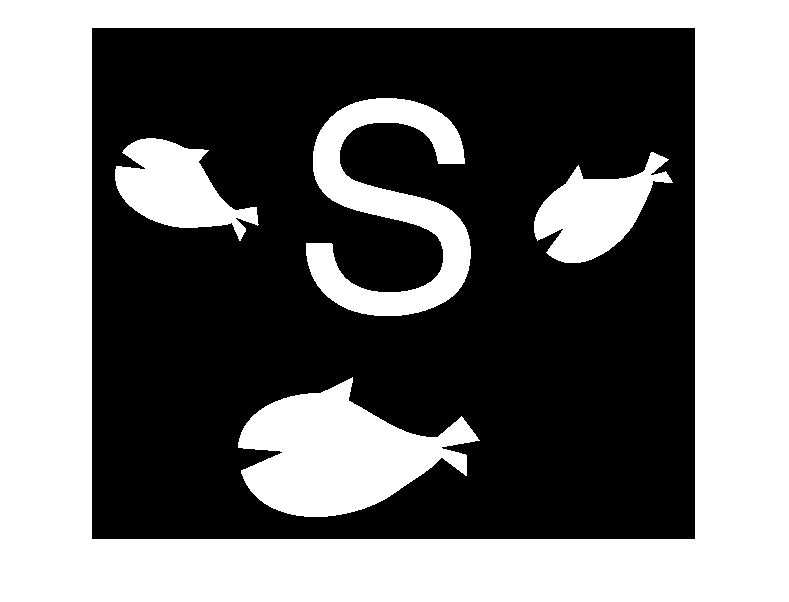

sharks = iread('sharks.png');  % load image sharks.png
[label, m] = ilabel(sharks);   % label all blobs (regions) and assign different values to each region. 

% convert the label image to a binary image, where label[u,v] = 2 will return 1, and the rest of the image will be zero
blob = (label == 1);           

imshow(sharks)

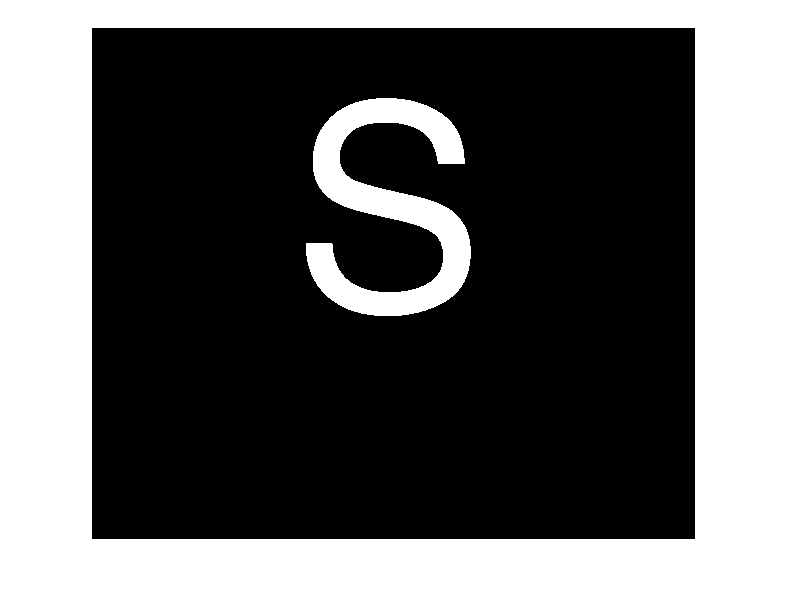

imshow(blob)

% summation of all pixel values in the blob image above (effectively just number of pixels with value of 1). 
sum(blob(:))

ans = 14899

% return those pixel coordinates that are equal to 1
[v,u] = find(blob);
about(u)

u [double] : 14899x1 (119.2 kB)


umin = min(u) % find the left boundary (min return the minimum value of u)

umin = 215

umax = max(u) % find the right boundary (max returns the maximum value of u)

umax = 379

vmin = min(v) % similar to above, return upper and lower boundary

vmin = 71

vmax = max(v)

vmax = 288

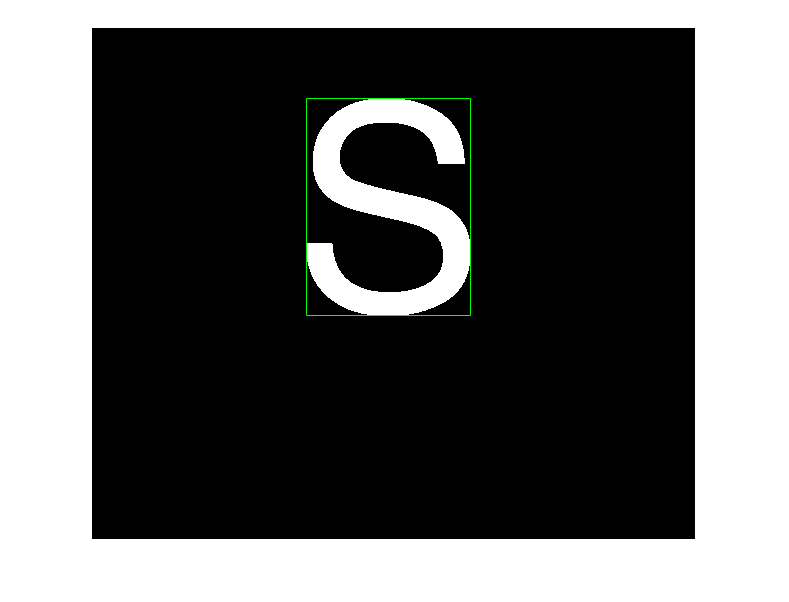

hh =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [215 379 379 215 215]
              YData: [71 71 288 288 71]
              ZData: [1×0 double]

  Show all properties


plot_box(umin, vmin, umax, vmax, 'g')  % g specifies the colour (Green). 

m00 = mpq(blob, 0, 0)  % The zeroth order moment (p = 0, q = 0)

m00 = 14899

uc = mpq(blob, 1, 0) / m00  % centre of the blob (p = 1, q = 0)

uc = 297.9890

vc = mpq(blob, 0, 1) / m00  % p = 0, q = 1

vc = 180.9785

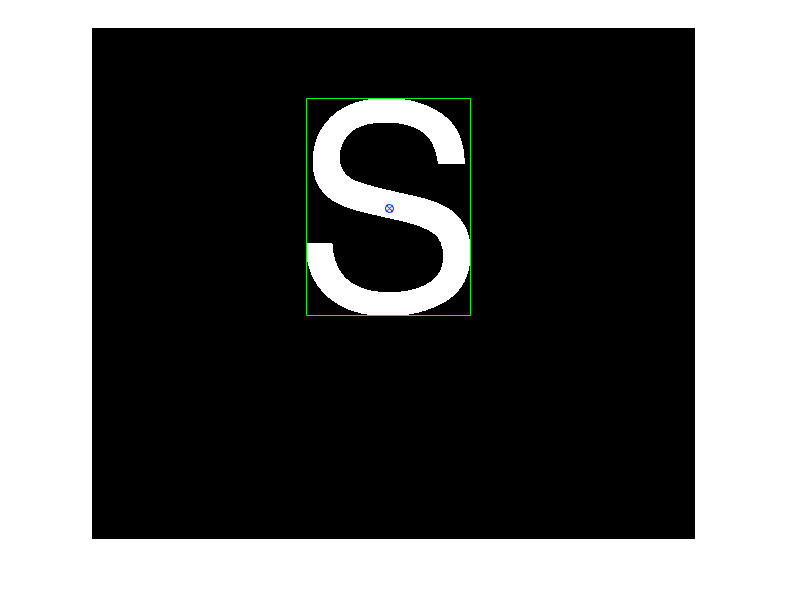

% r specifies color r, b represents colour blue. x and o specify the patterns to be ploted
hold on; plot(uc, vc, 'rx', uc, vc, 'bo');  

% Central moments
u20 = upq(blob, 2, 0); % p = 2, q = 0
u02 = upq(blob, 0, 2);  % p = 0, q = 2
u11 = upq(blob, 1, 1); % p = 1, q = 1
J = [ u20 u11; u11 u02]  % construct the matrix

J = 	1.0e+07 *

    3.3610    0.3234
    0.3234    6.7259


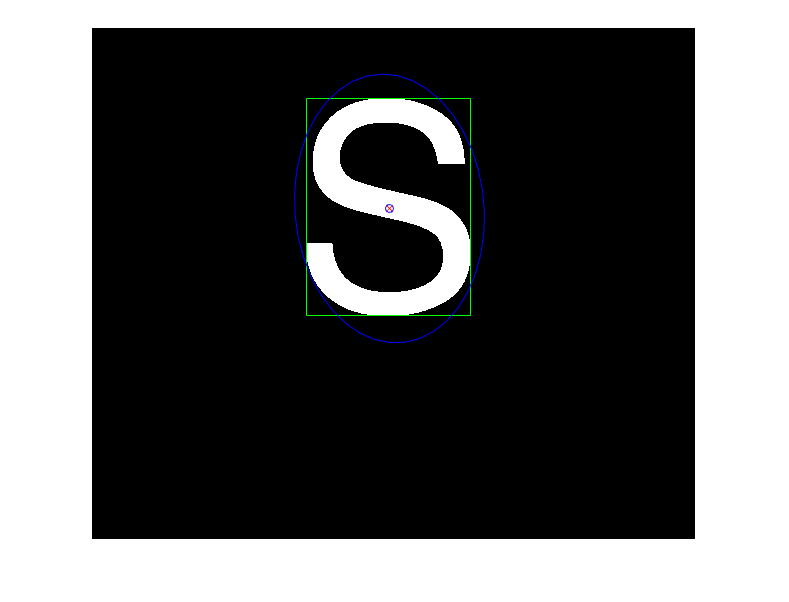

plot_ellipse(4*J/m00, [uc, vc], 'b');  % simply plot the ellipse. No worry about 4*J/m00 now

% eigen values and eigen vectors
lambda = eig(J) % 2 eigenvalues (2 dimension vector) 

lambda = 	1.0e+07 *

    3.3302
    6.7567


a = 2 * sqrt(lambda(2) / m00)  % a and b: radii of the ellipse

a = 134.6848

b = 2 * sqrt(lambda(1) / m00)

b = 94.5552

b/a

ans = 0.7020

[x,lambda] = eig(J);  % this returns both eigenvectors (x) and eigen values (lambda)
disp(x)

   -0.9955    0.0948
    0.0948    0.9955



v = x(:,end)    % one of the eigenvectors

v =     0.0948
    0.9955


atand( v(2)/v(1) )  % the angle of the eigenvector v. think of this as atan (y/x)

ans = 84.5600